center1 = 7.5/10;
center2 = 7.5/10;
spread1 = 1/10;
spread2 = 1/10;

event1_pdf = @(p) modified_gaussian(p,center1,spread1);
event2_pdf = @(p) modified_gaussian(p,center2,spread2);
event1_cdf = @(p) modified_gaussian_cdf(p,center1,spread1);
event2_cdf = @(p) modified_gaussian_cdf(p,center2,spread2);

% Looking at Event 1 Only
moneyline_struct = moneyline_solver(event1_pdf,event1_cdf); % FIX MONEYLINE SOLVER

if moneyline_struct.matched_answers
    event1_profit = moneyline_struct.profit_numerical
else
    event1_profit_numerical = moneyline_struct.profit_numerical
    event1_profit_newton = moneyline_struct.profit_newton
end

event1_profit_numerical = 0.0589

event1_profit_newton = 0


% Looking at Event 2 Only
moneyline_struct = moneyline_solver(event2_pdf,event2_cdf);

if moneyline_struct.matched_answers
    event2_profit = moneyline_struct.profit_numerical
else
    event2_profit_numerical = moneyline_struct.profit_numerical
    event2_profit_newton = moneyline_struct.profit_newton
end

event2_profit_numerical = 0.0589

event2_profit_newton = 0

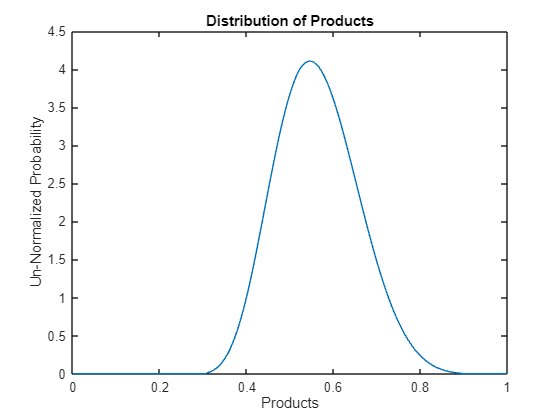


% Combine the Events

product_density = @(z) integral(@(p) event1_pdf(p).*event2_pdf(z./p)./p,0,1);
z_values = 0:.001:1;
product_values = zeros(1,length(z_values));
for index = 1:length(product_values)
    product_values(index) = product_density(z_values(index));
end

plot(z_values,product_values)
title('Distribution of Products')
xlabel('Products')
ylabel('Un-Normalized Probability')

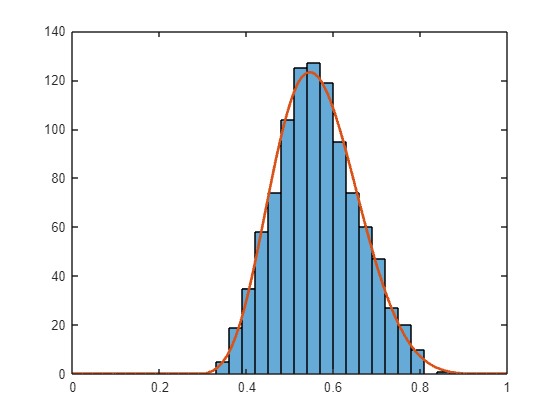


    % Use this distribution to generate 1e3 probability values and
    % numerically find the profitability of the moneyline

product_sample = nan(1,1e3);

for index = 1:1e3
    while isnan(product_sample(index))
        sample_value = rand();
        [~,z_index] = min(abs(z_values-sample_value));
        prob_of_use = product_values(z_index)/max(product_values);
        % I would love to contrast this method with the method that uses the 
        % inverse cdf with a random number input between [0 1] 

        r = rand();
        if r<=prob_of_use
            product_sample(index) = sample_value;
        end
    end
end
h = histogram(product_sample);
hold on
plot(z_values,product_values*1e6*(h.BinWidth)/sum(product_values),'LineWidth',2)
hold off


%% Product - 'Nuts and Bolts' numerical

product_spread = spread1*spread1*spread2*spread2 + spread1*spread1*center2*center2 + spread2*spread2*center1*center1

product_spread = 0.0114


num_samples = 1e3;
sample_probs = sort(product_sample);

sportsbook_profit_trad = 0;
palpha_final = nan;
pbeta_final = nan;

asymmetry_tolerance = 1; % In Basis Points of Total Money
% Would be interesting to plot max profitability as a function of asymmetry
% tolerance

f = waitbar(0,'Starting Process','Name','Solving For Traditional Sportsbook');
for palpha_index = 1:num_samples
    progress_value = (palpha_index^2+palpha_index)/(num_samples^2+num_samples);
    waitbar(progress_value,f,sprintf('%.1f Percent Complete',100*progress_value));
    for pbeta_index = 1:(palpha_index-1)
        palpha = sample_probs(palpha_index);
        pbeta = sample_probs(pbeta_index);
        alpha = 100*palpha/(1-palpha);
        beta = 100*pbeta/(1-pbeta);

        profit_favorite_win = length(1:pbeta_index) - 100/alpha*length(palpha_index:num_samples);
        profit_underdog_win = length(palpha_index:num_samples) - beta/100*length(1:pbeta_index);
        if abs(profit_favorite_win-profit_underdog_win) <= asymmetry_tolerance*num_samples/10000
            if max(profit_favorite_win,profit_underdog_win) > sportsbook_profit_trad
                sportsbook_profit_trad = max(profit_favorite_win,profit_underdog_win);
                palpha_final = palpha;
                pbeta_final = pbeta;
            end
        end

    end
end
close(f)
product_profit = sportsbook_profit_trad/num_samples

product_profit = 0.0581

#### OR (inclusive)

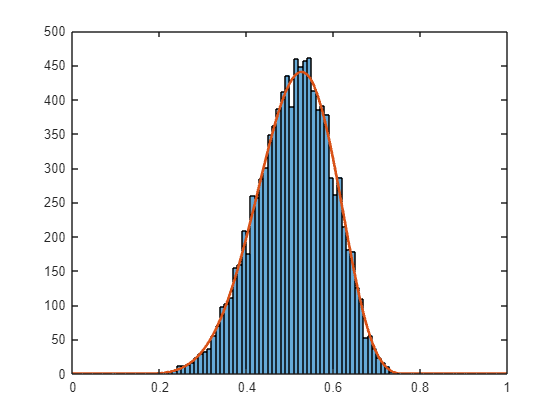

center1 = 3/10;
center2 = 3/10;
spread1 = 1/10;
spread2 = 1/10;

event1_pdf = @(p) modified_gaussian(p,center1,spread1);
event2_pdf = @(p) modified_gaussian(p,center2,spread2);
event1_cdf = @(p) modified_gaussian_cdf(p,center1,spread1);
event2_cdf = @(p) modified_gaussian_cdf(p,center2,spread2);
event1_inverse_cdf = @(p) modified_gaussian_inverse_cdf(p,center1,spread1);
event2_inverse_cdf = @(p) modified_gaussian_inverse_cdf(p,center2,spread2);

event1_values = event1_inverse_cdf(rand(1,1e4));
event2_values = event2_inverse_cdf(rand(1,1e4));

or_sample_values = nan(1,1e4);
for index = 1:1e4
    or_sample_values(index) = event1_values(index) + event2_values(index) - event1_values(index)*event2_values(index);
end
h = histogram(or_sample_values);
hold on

or_density = @(z) integral(@(p) event1_pdf(p).*event2_pdf((z-p)./(1-p))./(1-p),0,1);
z_values = 0:.001:1;
or_values = zeros(1,length(z_values));
for index = 1:length(or_values)
    or_values(index) = or_density(z_values(index));
end
A = 1e4/mean(or_values)*h.BinWidth;
plot(z_values,A*or_values,'LineWidth',2)

#### Dependent RVs

event1_inverse_cdf = @(p) modified_beta_inverse_cdf(p,.3,.01);

event1_values = event1_inverse_cdf(rand(1,1e4));
event2_values = event1_values+.05*rand(1,1e4);
event2_values = event2_values/max(event2_values);

% AND 
and_sample_values = nan(1,1e4);
for index = 1:1e4
    and_sample_values(index) = event1_values(index)*event2_values(index);
end

covariance_matrix = cov(event1_values,event2_values)

covariance_matrix =     0.0001    0.0003
    0.0003    0.0020


covariance_squared_matrix = cov(event1_values.^2,event2_values.^2)

covariance_squared_matrix =     0.0000    0.0003
    0.0003    0.0054



predicted_and_mean = mean(event1_values)*mean(event2_values) + covariance_matrix(1,2)

predicted_and_mean = 0.2475

actual_and_mean = mean(and_sample_values)

actual_and_mean = 0.2475


fprintf('\n')

predicted_and_var = var(event1_values)*var(event2_values) + mean(event1_values)^2*var(event2_values) + mean(event2_values)^2*var(event1_values) + ...
    covariance_squared_matrix(1,2) - covariance_matrix(1,2)^2 -2*covariance_matrix(1,2)*mean(event1_values)*mean(event2_values) 

predicted_and_var = 3.7541e-04

actual_and_var = var(and_sample_values)

actual_and_var = 3.7541e-04


% OR 
or_sample_values = nan(1,1e4);
for index = 1:1e4
    or_sample_values(index) = event1_values(index) + event2_values(index) - event1_values(index).*event2_values(index) ;
end

covariance_matrix = cov(event1_values,event2_values)

covariance_matrix =     0.0001    0.0003
    0.0003    0.0020


covariance_squared_matrix = cov((1-event1_values).^2,(1-event2_values).^2)

covariance_squared_matrix = 1.0e-03 *

    0.1955    0.1222
    0.1222    0.2466



predicted_or_mean = mean(event1_values) + mean(event2_values) - mean(event1_values)*mean(event2_values) - covariance_matrix(1,2)

predicted_or_mean = 0.8769

actual_or_mean = mean(or_sample_values)

actual_or_mean = 0.8769


fprintf('\n')

predicted_or_var = var(event1_values)*var(event2_values) + (1-mean(event1_values))^2*var(event2_values) + (1-mean(event2_values))^2*var(event1_values) + ...
    covariance_squared_matrix(1,2) - covariance_matrix(1,2)^2 -2*covariance_matrix(1,2)*(1-mean(event1_values))*(1-mean(event2_values))

predicted_or_var = 0.0010

actual_or_var = var(or_sample_values)

actual_or_var = 0.0010